# Cocoan 101 Week 10 (21.04.30): Predictive modeling

## Predictive modeling using CV-PCR

by Soo Ahn Lee

## 1. Basic settings

[~, ~, plsprojectdir, plssyncdir, toolboxdir] = set_vary_PLS('iMacPro4');
basedir = '/Users/sooahn/Desktop/Cocoan101';
spider_dir = fullfile(toolboxdir, 'CanlabCore/CanlabCore/External/spider');
addpath(genpath(spider_dir));

dat_temp = fmri_data(which('gray_matter_mask.nii'), which('gray_matter_mask.nii'));
roi_imgs = filenames(fullfile(plssyncdir, 'data/rois/*nii'));

## 2. Prepare data

#### [Experiment design]

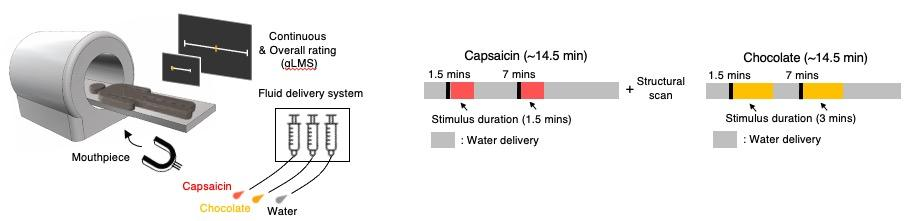

Number of participants: 58

Task: continuously rate their subjective feelings of pleasantness and unpleasantness

Stimuli: Capsaicin (painful/unpleasantness), Chocolate fluid (pleasantness) 

#### [Beta images obtained for data analysis]

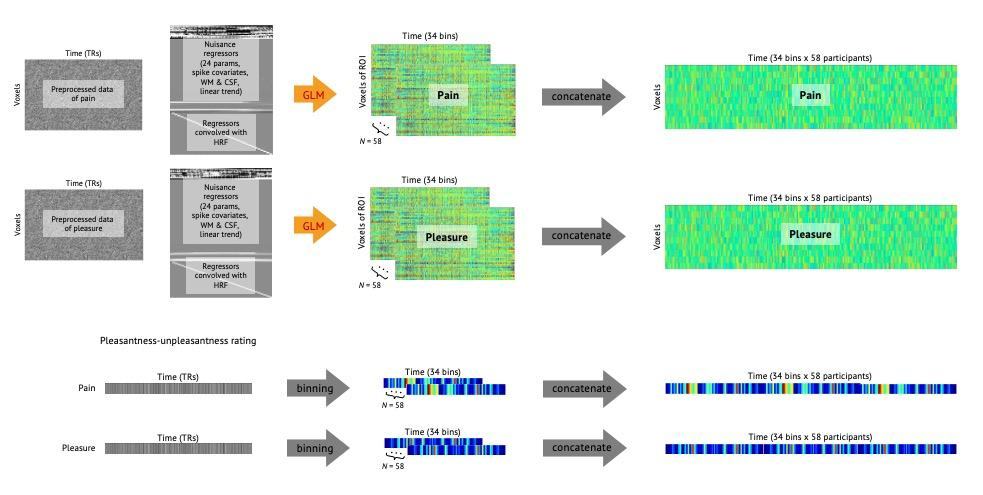

Final outcome: 34 bins X 58 individuals concatenated data per each condition

load(fullfile(plsprojectdir,'data/34bin_betamap/betadat_normalized_58subjs.mat'));

% caps
dat_caps = dat_temp;
dat_caps.dat = betadat_34bin.caps.dat;
dat_caps.Y = betadat_34bin.caps.y;

% select region of interest (optional)
dat_caps_roi = apply_mask(dat_caps,roi_imgs{1});  % amygdala

% check dat.Y
plot(dat_caps_roi.Y);

% check dat.dat
imagesc(dat_caps_roi.dat);
ylabel('voxels');
xlabel('observations')
colorbar;

% sweet
dat_sweet = dat_temp;
dat_sweet.dat = betadat_34bin.sweet.dat;
dat_sweet.Y = betadat_34bin.sweet.y;

% select region of interest (optional)
dat_sweet_roi = apply_mask(dat_sweet,roi_imgs{1});  % amygdala

% check dat.Y
plot(dat_sweet_roi.Y);

% check dat.dat
imagesc(dat_sweet_roi.dat);
ylabel('voxels');
xlabel('observations');
colorbar;

## 3. Train CV-PCR model using leave-one-out cross-validation

whfold = repmat(1:58, 34, 1);
whfold = whfold(:);

% caps
[~, stats_caps] = predict(dat_caps_roi, 'algorithm_name', 'cv_pcr', 'nfolds', whfold, 'numcomponents', 10);

% sweet
[~, stats_sweet] = predict(dat_sweet_roi, 'algorithm_name', 'cv_pcr', 'nfolds', whfold, 'numcomponents', 10);

## 4. Visualize outputs

% caps
% within-individual prediction r
clear r;
for j = unique(whfold)'
    r(j,1) = corr(stats_caps.Y(whfold==j), stats_caps.yfit(whfold==j));
end
mean(r)

% plot y & yfit
h = plot_y_yfit(reshape(stats_caps.Y,34,58), reshape(stats_caps.yfit,34,58));

% bootstrap
bootres = boot_mean_wani(r, 10000);

% weight map
orthviews(stats_caps.weight_obj);

% averaged cv weight map
temp = dat_caps_roi;
temp.dat = mean(cat(2,stats_caps.other_output_cv{:,1}),2);
orthviews(temp);

% sweet
% within-individual prediction r
clear r;
for j = unique(whfold)'
    r(j,1) = corr(stats_sweet.Y(whfold==j), stats_sweet.yfit(whfold==j));
end
mean(r)

% plot y & yfit
h = plot_y_yfit(reshape(stats_sweet.Y,34,58), reshape(stats_sweet.yfit,34,58));

% bootstrap
bootres = boot_mean_wani(r, 10000);

% weight map
orthviews(stats_sweet.weight_obj);

% averaged cv weight map
temp = dat_temp;
temp.dat = mean(cat(2,stats_stats_sweetcaps.other_output_cv{:,1}),2);
orthviews(temp);